clear;
ott.warning('once');
ott.change_warnings('off');

Generate a Gaussian beam (NA = 0.0451)

n_medium = 1.0;         % Index in vacuum
wavelength0 = 1064e-9;  % Vacuum wavelength (m)

% Numerical aperture of the beam
% Assume a w0 = 7.5 um waist,
% the half opening angle is 
% lim_{z->\infty} arctan(w(z) / z),
% or `theta = lambda / (pi * w0 * n)` 
% in paraxial approx.
% where n = 1 is the index of the medium
% NA = n * sin(theta)
NA = 0.0451;

% Number of beam shape coefs to be used
Nmax = 200;

% Polarization in Jones vector. [ 1 0 ]: linear polarization in x
% [ 0 1 ]: y-polarized. [ 1 -i ] and [ 1 i ] are circularly polarized.
polarisation = [1 0];

% Spatial mode of the incident light in the Laguerre-Gauss
% basis. Fundamental Gaussian profile = [0 0].
lg_mode = [0 0];

beam_offset = [0; 0; 0];

beam = ott.BscPmGauss('type','lg', 'mode', lg_mode, ...
                      'polarisation', polarisation, 'NA', NA,...
                      'offset', beam_offset, 'index_medium', n_medium, ...
                      'wavelength0', wavelength0, ...
                      'Nmax', Nmax);

% Normalize the beam power before moving forward
beam.power = 1.0;

Calculate the T-matrix for the particle

n_particle = 1.51;
radius = 5e-6;  % 10 um diameter

% `Tmatrix.simple` will automatically choose a method
% for T matrix estimation
T = ott.Tmatrix.simple('sphere', radius, 'wavelength0', wavelength0, ...
   'index_medium', n_medium, 'index_particle', n_particle, 'Nmax', Nmax);

disp(['The mass of the sphere is ', num2str(m * 1e9 * 1e3), ' ng'])

The mass of the sphere is 0.94248 ng


Calculate the equlibrium position in the z-direction

beam.basis = 'regular';

% Calculate the force along z

% Displacement from focus (m)
z = [0;0;1] .* linspace(3.9, 4.1, 50) .* 1e-4;
fz = ott.forcetorque(beam, T, 'position', z);

Relevant parameters for the beam and the particle

power = 50e-3;                  % Laser power (W)
nPc = power .* n_medium / 3e8;  % power * n / vacuum_speed

density = 1.8 * (1e-3/(1e-6));  % g/cm^3 -> kg/m^3
volume = (4/ 3) * pi * (radius^3);
m = density * volume;           % kg

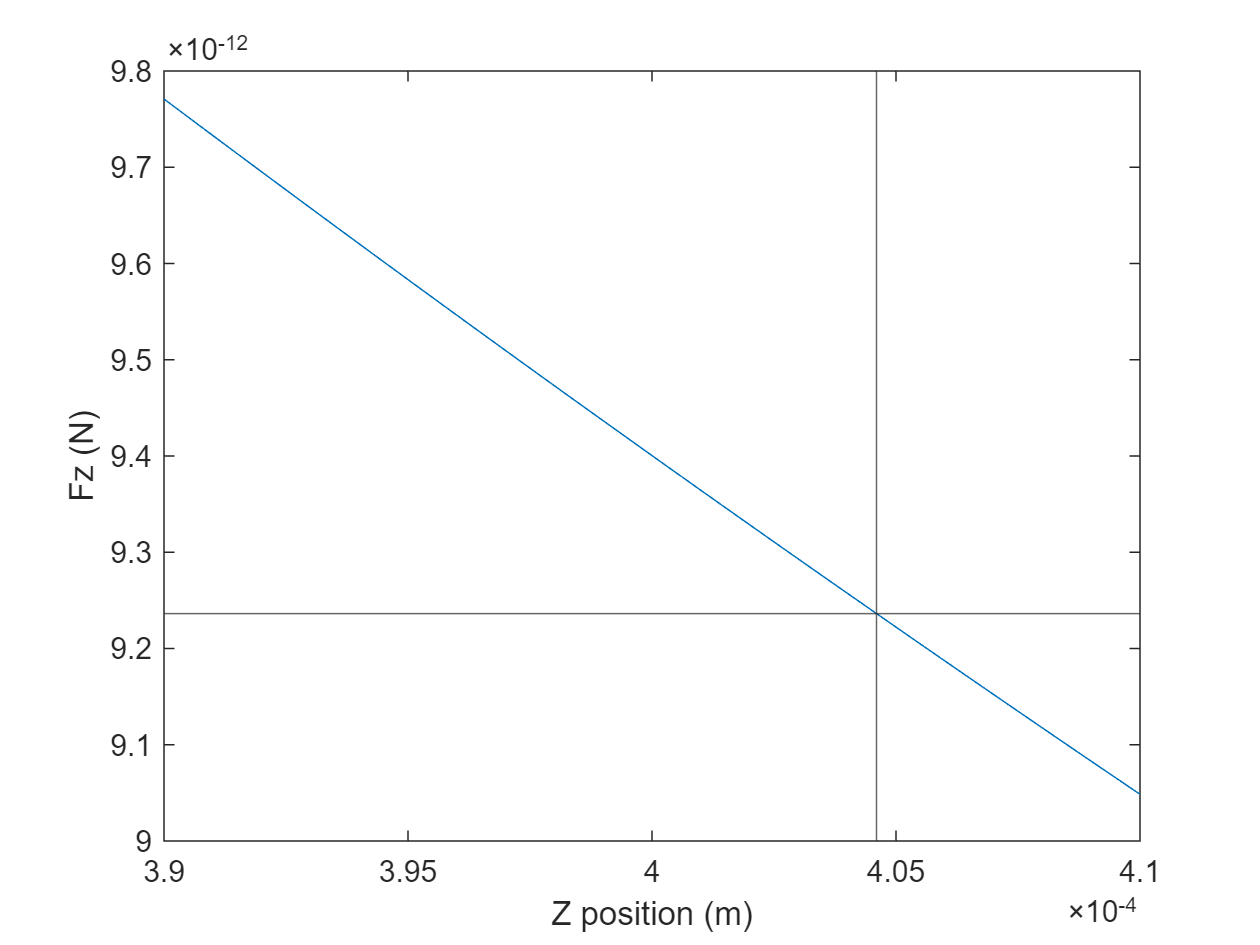

fz_si = fz .* nPc;
mg = m * 9.8;

figure();
plot(z(3, :), fz_si(3, :));
xlabel('Z position (m)');
ylabel('Fz (N)');

yline(mg);        % Gravity experienced by the sphere
xline(4.046e-4);  % The equlibirum position is 4.046e-4 m above the focal plane

Estimate trap stiffness around the equilibrium point

z_eq = 4.046e-4;  % meter

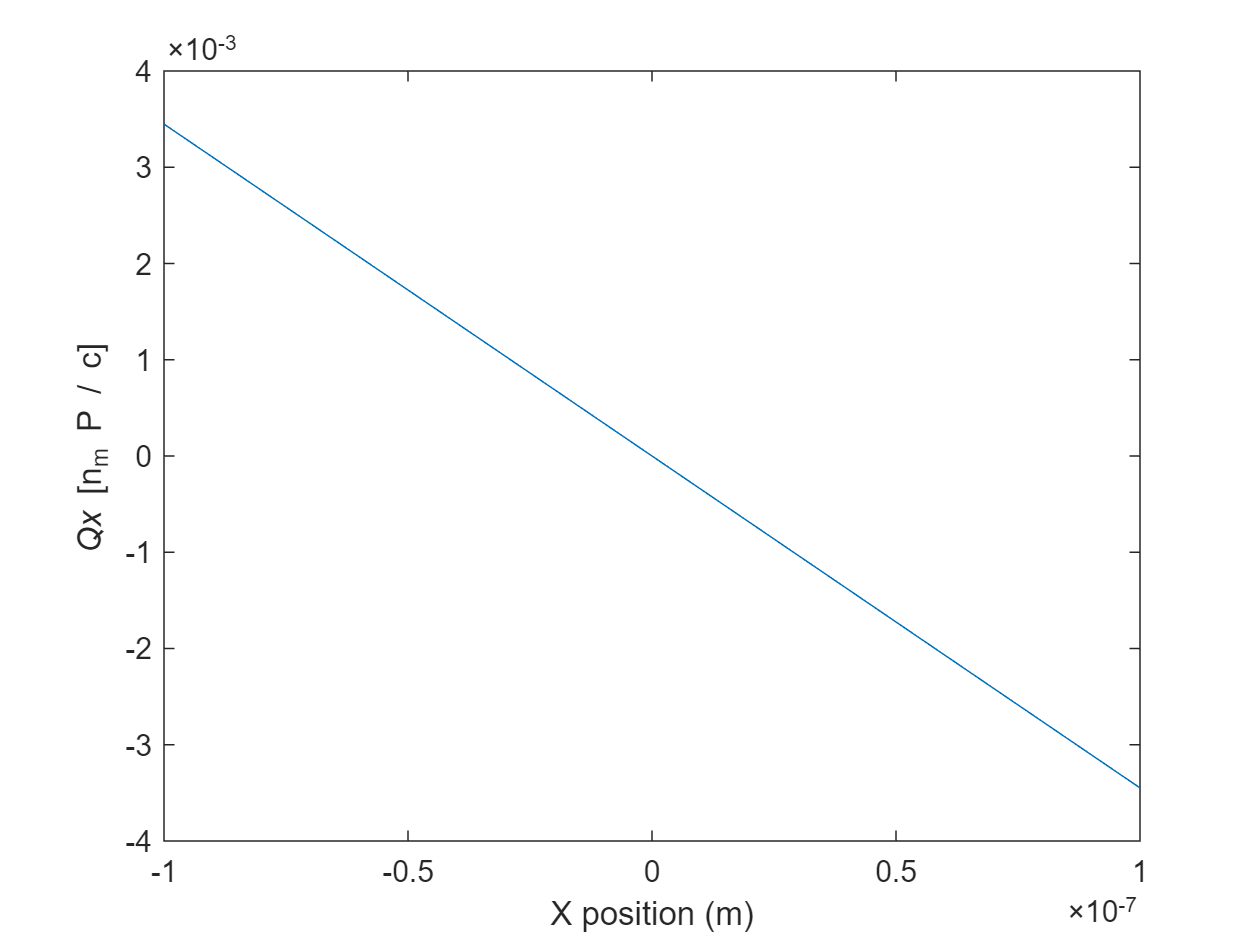

beam.basis = 'regular';
x = [1; 0; z_eq] .* linspace(-10, 10, 10) .* 1e-8;
fx = ott.forcetorque(beam, T, 'position', x);

figure();
plot(x(1, :), fx(1, :));
xlabel('X position (m)');
ylabel('{\it Qx} [n_m P / c]');

plot(x(1, :), fx(1, :));
xlabel('X position (m)');
ylabel('{\it Qx} [n_m P / c]');

fx_si = fx .* nPc;
kx = (fx_si(1, 1) - fx_si(1, end)) / (x(1, end) - x(1, 1));
omega_x = sqrt(kx/m);
freq_x = omega_x / (2 * pi);

display(['Trapping frequency in x is ', num2str(freq_x), ' Hz']);

Trapping frequency in x is 393.0166 Hz


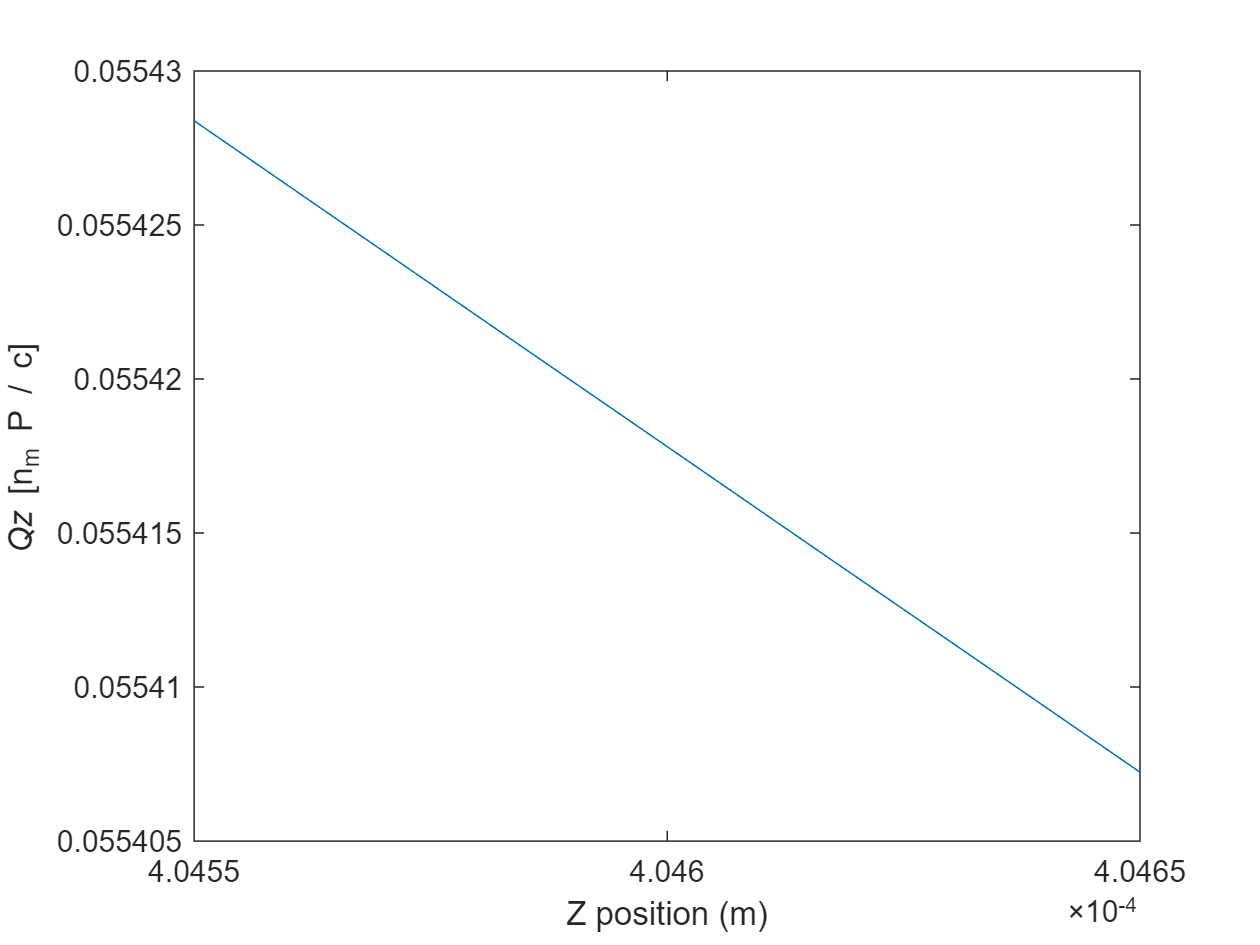

beam.basis = 'regular';
z = [0; 0; z_eq] + [0; 0; 1] .* linspace(-5, 5, 10) .* 1e-8;
fz = ott.forcetorque(beam, T, 'position', z);

figure();
plot(z(3, :), fz(3, :));
xlabel('Z position (m)');
ylabel('{\it Qz} [n_m P / c]');

fz_si = fz .* nPc;
kz = (fz_si(3, 1) - fz_si(3, end)) / (z(3, end) - z(3, 1));
omega_z = sqrt(kz/m);
freq_z = omega_z / (2 * pi);

display(['Trapping frequency in z is ', num2str(freq_z), ' Hz']);

Trapping frequency in z is 30.7767 Hz
